# **SISTEMAS DE CONTROL DISCRETO                                **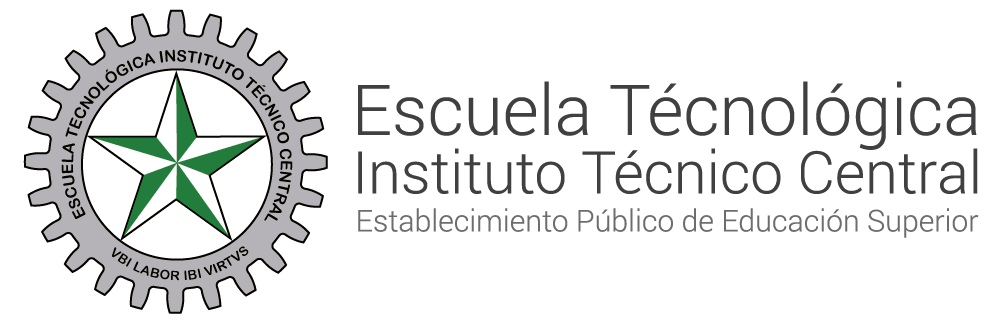

# **Lugar Geometrico de las Raícez **

#### Autor ING. JHEYSON FABIAN VILLAVISAN BUITRAGO 

#### Coautor: Anderson Stewar Chaves Melo

#### INTRODUCCIÓN

la estabilidad relativa del sistema de control en tiempo discreto puede ser investigada en relación con el circulo unitario en el plano z. Por ejemplo, si los polos en lazo cerrado son complejas conjugadas y ocurren dentro del circulo unitario, la respuesta escalon unitario sera oscilatoria. Ademas de las caracteristicas de respuesta transitoria de un sistema dado, a menudo resulta necesario investigar los efectos de la ganancia del sistema o del periodo de muestreo del sistema sobre la estabilidad absoluta y relativa del sistema en lazo cerrado. Para estos fines, el metodo del lugar geometrico de las raices es muy util. El metodo del lugar geometrico de las raices desarrollado para sistemas en tiempo continuo puede ser extendido sin modificaciones a sistemas en tiempo discreto, excepto por que el limite de estabilidad queda modificado del eje jw en el plano s al circulo unitario en el plano z. La razón por la cual el rnetodo del lugar geometrico de las raices puede extenderse a sistemas en tiempo discreto es porque la ecuación caracteristica correspondiente al sistema en tiempo discreto tiene la misma forma que la del sistema en tiempo continuo en el plano s. Sin embargo, la localización de los polos para los sistemas en lazo cerrado en el plano z debe ser interpretada en forma distinta a la correspondiente en el plano s.

#### REGLAS GENERALES PARA LA CONSTRUCCIÓN DE LOS LUGARES GEOMETRICOS DE LA RAÍZ:

- Obtener la ecuación caracteristica

- Determine los polos y ceros en el plano z

- Determine el lugar geometrico de las raices sobre el eje real

- Determinar las asíntotas y sus ángulos

- Determinar la intersección de las asíntotas con el eje real

- Encontrar los puntos de ruptura

- Encontrar la estabilidad mediante el criterio de JURY

#### En esta sección demostraremos la aplicación del metodo del lugar geometrico de las raices al diseño de sistemas de control en tiempo discreto o digitales por medio de los siguientes ejercicios propuestos:

- las ecuaciones características del sistema de control en tiempo discreto se dan a continuación, construya el lugar geométrico de las raíces para k>0. determine el valor marginal de k para estabilidad.

## 
$$z^2 +\left(0\ldotp 15k-1\ldotp 5\right)z+1=0$$


## PASO A PASO

### Paso 1

Obtener la ecuación característica:


$$1+ F(z)=0$$


Como ya nos dan la ecuación característica podemos reconstruir su función de transferencia de lazo abierto de la siguiente manera:

- Ecuación caracteristica: 

 
$$z^2 +\left(0\ldotp 15k-1\ldotp 5\right)z+1=0$$


- **Dividir por los términos que no dependen de K: **Dividimos toda la ecuación entre $z^2 -1\ldotp 5z+1$ que corresponde al sistema sin la ganancia K.


$$\frac{z^2 +\left(0\ldotp 15k-1\ldotp 5\right)z+1}{z^2 -1\ldotp 5z+1}=0$$


Descomponiendo esta expresión:


$$\frac{z^2 -1\ldotp 5z+1}{z^2 -1\ldotp 5z+1}+\frac{0\ldotp 15\textrm{kz}}{z^2 -1\ldotp 5z+1}=0$$


Simplificando el primer término se reduce a 1, dejando:


$$1+\frac{0\ldotp 15\textrm{kz}}{z^2 -1\ldotp 5z+1}=0$$


Identificando nuestra función de transferencia como:


$$K\frac{0\ldotp 15z}{z^2 -1\ldotp 5z+1}$$


clear all
clc
syms z K real
char_eq = z^2 + (0.15*K - 1.5)*z + 1; % Ecuacion caracteristica
numerador = [0.15 0];           % Numerador del sistema
denominador = [1 -1.5 1];           % Denominador
ts = 1;                         % Tiempo de muestreo
fprintf('*** Función de Transferencia Discreta ***\n');

*** Función de Transferencia Discreta ***


sistema = tf(numerador, denominador, ts)


sistema =
 
      0.15 z
  ---------------
  z^2 - 1.5 z + 1
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


### Paso 2

Determine los polos y ceros en el plano z:

Los polos de la función de transferencia en lazo abierto son las raíces de la ecuación característica cuando K = 0, mientras que los ceros son las raíces para K = ∞

- Es así que hallamos los polos de la ecuación caracteristica cuando K=0;


$$z^2 -1\ldotp 5z+1=0$$


donde:

a= 1,  b= -1.5,  c= 1.

aplicando la ecuación cuadrática se obtiene:

$\frac{1\ldotp 5\pm \sqrt{{1\ldotp 5}^2 -4\left(1\right)\left(1\right)}}{2\left(1\right)}$  =  0.7500 ± j0.6614

fprintf('*** Calcular polos del sistema ***\n');

*** Calcular polos del sistema ***


polos = pole(sistema)

polos =    0.7500 + 0.6614i
   0.7500 - 0.6614i


- Aquellos que corresponden a K= ∞ son los ceros;


$$\lim_{K=\infty } \;\frac{1}{K}\lbrack z^2 +\left(0\ldotp 15k-1\ldotp 5\right)z+1\rbrack =0$$



$$0\ldotp 15z=0$$



$$z=0$$


fprintf('*** Calcular ceros del sistema ***\n');

*** Calcular ceros del sistema ***


ceros = zero(sistema)

ceros = 0

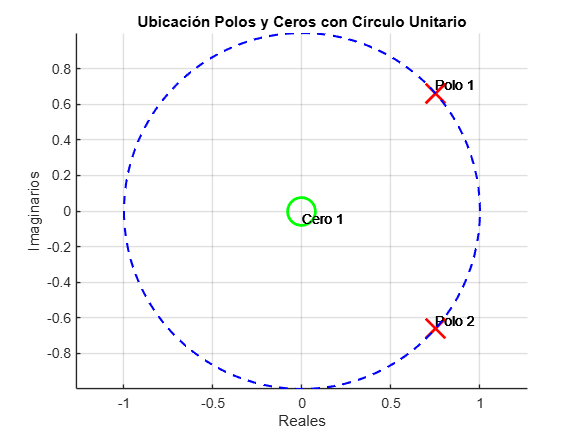

hold on;

% Polos (x en rojo)
plot(real(polos), imag(polos), 'rx', 'MarkerSize', 20, 'LineWidth', 2); 
% Ceros (o en verde)
plot(real(ceros), imag(ceros), 'go', 'MarkerSize', 20, 'LineWidth', 2); 

% Etiquetas de polos
for k = 1:length(polos)
    text(real(polos(k)), imag(polos(k)), sprintf('Polo %d', k), 'VerticalAlignment', 'bottom');
end

% Etiquetas de ceros
for k = 1:length(ceros)
    text(real(ceros(k)), imag(ceros(k)), sprintf('Cero %d', k), 'VerticalAlignment', 'top');
end

% Graficar el círculo unitario
theta = linspace(0, 2*pi, 100); % Generar un vector de ángulos
x = cos(theta); % Coordenadas X del círculo
y = sin(theta); % Coordenadas Y del círculo
plot(x, y, 'b--', 'LineWidth', 1.5); % Dibujar el círculo unitario con línea azul discontinua

% Etiquetas y título
xlabel('Reales');
ylabel('Imaginarios');
title('Ubicación Polos y Ceros con Círculo Unitario');

% Establecer el aspecto igual para que el círculo se vea como un círculo
axis equal;
grid on;

### Paso 3

Determine el lugar geometrico de las raices sobre el eje real:

EI lugar geometrico de las raices sobre el eje real se determina por los polos en lazo abierto y los ceros que quedan sobre el, Los polos y ceros complejos conjugados de la función de transferencia  en lazo abierto no tienen efecto en la localización del lugar geometrico de las raices sobre el eje real porque la contribución angular de los polos y ceros de un par de polos complejos conjugados es de 360° sobre el eje real. Cada parte del lugar geometrico de las raices sobre el eje real se extiende sobre un segmenro desde un polo o cero hasta otro polo o cero.

-  Hay dos polos complejos, uno cero en z = 0 y otro cero en -∞:


$$\lim_{K=\infty } \;z=\lim_{K=\infty } \;\frac{-\left(0\ldotp 15k-1\ldotp 5\right)\pm \sqrt{{\left(0\ldotp 15k-1\ldotp 5\right)}^2 -4}}{2}$$


=$\begin{array}{l}
\left\lbrace \begin{array}{ll}
-\;\left(0\ldotp 15k-1\ldotp 5\right)+\left(0\ldotp 15k-1\ldotp 5\right)=0 & \\
-\infty -\infty =-\infty  & 
\end{array}\right.\\

\end{array}$

Por lo tanto, el LGR comprende dos ramas que comienzan en z = 0,7500 ± j0,6614 y terminando en z = 0 y z = -∞

Como los polos son complejos, el único intervalo real que pertenece al lugar de la raíz es (-∞,0]

- **Cantidad de ramas: **En un sistema de control, el número de ramas en el **lugar geométrico de las raíces (Root Locus)** siempre coincide con el grado del denominador, es decir, el número de polos del sistema. Por lo tanto, este sistema tiene **2 ramas** en el lugar de las raíces.

- **Explicación de las ramas: **Cada rama del lugar de las raíces describe cómo un polo se desplaza en el plano complejo a medida que varía el parámetro k (la ganancia). Para este sistema hay **dos polos iniciales** donde Las dos ramas describen el movimiento de estas raíces para diferentes valores de k.

Es así que podemos decir que para encontrar la cantidad de ramas del sistema donde $n=\textrm{polos}$ y $m=\textrm{ceros}$ sabemos que:


$$n-m$$


En este caso:

- $n=2,\;m=1$ por lo que:

Numero de ramas= $n-m=2-1=1$ (rama que va hacia el infinito).

fprintf('polos del sistema\n');

polos del sistema


n_polos = length(polos)

n_polos = 2

fprintf('Ceros del sistema\n');

Ceros del sistema


n_ceros = length(ceros)

n_ceros = 1

n_asintotas = n_polos - n_ceros

n_asintotas = 1

La otra rama del LGR conectará uno de los polos con el único cero disponible.

### Paso 4

Determinar las asíntotas y sus ángulos:

Aplicando la formula:


$$\frac{180\left(2N+1\right)}{n-m}$$


Por lo que al remplazar la iteracion de N obtenemos:


$$\frac{180\left(2N+1\right)}{2-1}\to \frac{180\left(2\left(0\right)+1\right)}{1}=180\degree$$


N=0;
Angulo = (180 * (2 * N + 1)) / (n_asintotas)

Angulo = 180

Por lo tanto, la única asíntota será horizontal y apuntará hacia la izquierda en el eje real

### Paso 5

Determinar la intersección de las asíntotas con el eje real:

Esto Representa la ubicación en el eje real donde las asíntotas de las ramas que tienden al infinito se intersectan. Este punto actúa como el origen de las asíntotas que se extienden hacia el infinito en el plano complejo.

Esta dado por la siguiente formula:


$$\frac{\sum \textrm{Polos}-\sum \textrm{Ceros}}{n-m}$$


Donde:

- ∑Polos: Es la suma de las ubicaciones de todos los polos del sistema.

- ∑Ceros: Es la suma de las ubicaciones de todos los ceros del sistema.

- *n*: Número de polos del sistema.

- *m*: Número de ceros del sistema.

- *n*−*m*: Es el número de ramas que tienden al infinito.

polos = pole(sistema)

polos =    0.7500 + 0.6614i
   0.7500 - 0.6614i


ceros = zero(sistema)

ceros = 0

Obteniendo de nuestros calculos:


$$\frac{\left(0\ldotp 75+0\ldotp 75\right)-0}{2-1}=1\ldotp 5$$


interseccion = sum(polos)-sum(ceros)/n_asintotas

interseccion = 1.5000

En el lugar geométrico de las raíces, las ramas que se dirigen al infinito se originarán en el punto *z*=1.5 del eje real y seguirán los ángulos correspondientes lo cual en este caso es irrelevante ya que el angulo hallado es horizontal al eje real

### Graficar el Lugar Geométrico de las Raíces (LGR)

% Graficar el Lugar Geométrico de las Raíces (LGR)
fprintf('*** Graficar el Lugar Geométrico de las Raíces (LGR) ***\n');

*** Graficar el Lugar Geométrico de las Raíces (LGR) ***


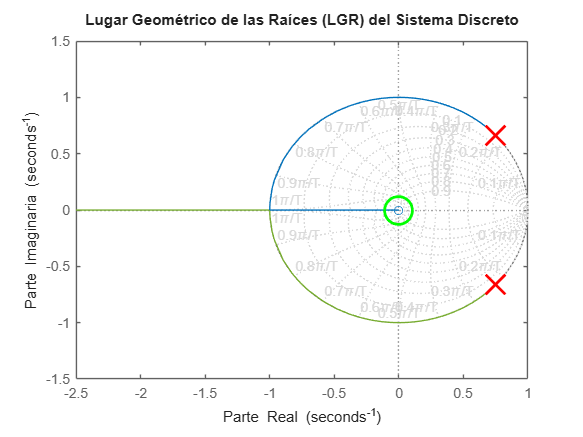

figure;
rlocus(sistema);
title('Lugar Geométrico de las Raíces (LGR) del Sistema Discreto');
xlabel('Parte Real');
ylabel('Parte Imaginaria');
grid on;

hold on;
plot(real(polos), imag(polos), 'rx', 'MarkerSize', 20, 'LineWidth', 2); % Polos (x en rojo)
plot(real(ceros), imag(ceros), 'go', 'MarkerSize', 20, 'LineWidth', 2); % Ceros (o en verde)

for k = 1:length(polos)
    text(real(polos(k)), imag(polos(k)), sprintf('Polo %d', k), 'VerticalAlignment', 'bottom');
end
for k = 1:length(ceros)
    text(real(ceros(k)), imag(ceros(k)), sprintf('Cero %d', k), 'VerticalAlignment', 'top');
end

### Paso 6

Encontrar los puntos de ruptura:

Los **puntos de ruptura** en el **Lugar Geométrico de las Raíces (LGR)** son los puntos en los que las ramas del LGR, que representan el movimiento de los polos del sistema al variar la ganancia K, se separan o se unen. Estos puntos ocurren típicamente en el eje real, donde las ramas dejan de moverse en línea recta y comienzan a curvarse hacia el plano complejo.

Si un lugar geométrico de las raíces se presenta entre dos polos adyacentes en lazo abierto sobre el eje real, entonces existira por lo menos un punto de ruptura de salida entre ambos polos. En forma similar, si el lugar geometrico de las raices se presenta entre dos ceros adyacentes (un cero pudiera estar localizado en-$\infty$) sobre el eje real, entonces siempre existira por lo menos un punto de  ruptura de entrada entre los dos ceros.

Si la ecuación caracteristica


$$1+F\left(z\right)=0$$


se escribe en la forma


$$1+\frac{\textrm{KB}\left(z\right)}{A\left(z\right)}=0$$


entonces


$$K=-\frac{A\left(z\right)}{B\left(z\right)}$$


 y los puntos de ruptura de salida y de entrada (que corresponden a raices multiples) se pueden determinar a partir de las raices de


$$\frac{\textrm{dk}}{\textrm{dz}}=-\frac{A\prime \left(z\right)B\left(z\right)-A\left(z\right)B\prime \left(z\right)}{B^2 \left(z\right)}$$


- Es así que paras nuestro sistema debe haber un punto de ruptura entre los ceros z = -$\infty$ y z = 0


$$K=-\frac{z^2 -1\ldotp 5z+1}{0\ldotp 15z}$$


$\frac{\textrm{dk}}{\textrm{dz}}=-\frac{\left(2z-1\ldotp 5\right)0\ldotp 15z-0\ldotp 15\left(z^2 -1\ldotp 5z+1\right)}{{\left(0\ldotp 15z\right)}^2 }$ = - $\frac{{0\ldotp 15z}^2 -0\ldotp 15}{{0\ldotp 0225z}^2 }$ = 0

Resolviendo para z obtenemos:


$$z=\pm 1$$


K_expr = solve(char_eq == 0, K);  % Express K in terms of z
dK_dz = diff(K_expr, z);
break_points = solve(dK_dz == 0, z);
disp('Punto de ruptura:');

Punto de ruptura:


disp(double(break_points));

    -1
     1



El punto de ruptura está en z = -1, ya que z = +1 no pertenece al lugar geométrico de la raíz.

 El valor de K para este punto es:


$$K\left(-1\right)=-\frac{z^2 -1\ldotp 5z+1}{0\ldotp 15z}=\frac{1+1\ldotp 5+1}{0\ldotp 15}=23\ldotp 33$$


K_break = double(subs(K_expr, z, -1));
disp('K en el punto de ruptura (z = -1):');

K en el punto de ruptura (z = -1):


disp(K_break);

   23.3333



### Paso 7

Encontrar la estabilidad mediante el criterio de JURY

- El criterio de estabilidad de Jury es un método analítico utilizado para determinar la estabilidad de sistemas en tiempo discreto. Su objetivo es verificar si todas las raíces del polinomio característico están dentro del círculo unidad en el plano *z*, condición necesaria y suficiente para que el sistema sea estable.

Para nuestra ecuación dado que se trata de un sistema de segundo orden, las condiciones de estabilidad de Jury pueden escribir se como:

- 
$$\left|\textrm{a2}\right|<\textrm{a0}$$


- 
$$P\left(1\right)>0$$


- 
$$P\left(-1\right)>0\ldotp \;\;\;\;\;\;\;\;n=2=\textrm{par}$$


donde:


$$\begin{array}{l}
\textrm{a0}=1\\
\textrm{a1}=\left(0\ldotp 15k-1\ldotp 5\right)\\
\textrm{a2}=1
\end{array}$$


Evaluando las condiciones obtenemos que:

- 
$$\left|1\right|<1$$


lo cual no es cierto. Más bien, tenemos:


$$\left|1\right|=1$$


          2. $P\left(1\right)$= 1 + (0.15K - 1.5) + 1 $>0$

Resolviendo obtenemos que:

 
$$0\ldotp 5+0\ldotp 15K>0$$


  
$$K>-3\ldotp 33$$


          3. $P\left(-1\right)$= -1 - 0.15K + 1.5) + 1 $>0$

Resolviendo obtenemos que:


$$3\ldotp 5-0\ldotp 15K>0$$



$$K<23\ldotp 33$$


 Para estabilidad, la constante de ganancia K debe satisfacer las desigualdades de las tres condiciones. Por lo tanto:


$$-3\ldotp 33<K<23,33$$


 EI rango de la constante de ganancia K para estabilidad esta entre $-3\ldotp 33\;y\;23\ldotp 33\ldotp$

En nuestro sistema el coeficiente constante $\mathrm{a2}=1$ en la ecuación característica significa que **los polos no pueden alejarse del círculo unitario** sin abandonar la estabilidad, esto nos demuestra que nuestro sistema sera criticamente estable siempre en el rango de estabilidad para K ya establecido.

% Configuración inicial
clear; clc; close all;

% Valores de K
K =5 % Valores representativos de K

K = 5

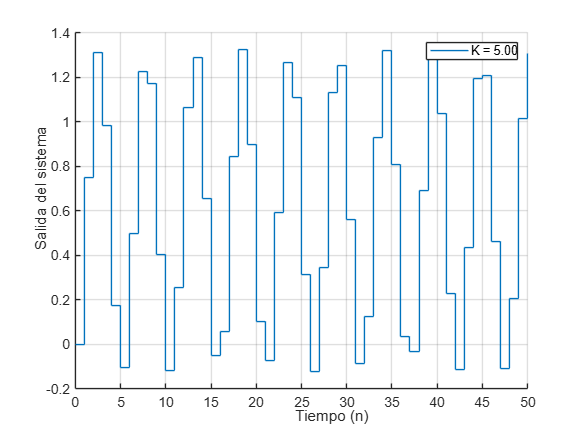

Ts = 1; % Tiempo de muestreo

% Crear figura para graficar respuestas al escalón
figure;
hold on;

num = [0.15*K 0];          % Numerador 
den = [1, 0.15*K-1.5, 1];  % Denominador 

    % Crear sistema de tiempo discreto
    sys = tf(num, den, Ts);

    % Generar la respuesta al escalón unitario
    [y, t_out] = step(sys, 0:50);

    % Graficar la respuesta
    stairs(t_out, y, 'DisplayName', sprintf('K = %.2f', K));


xlabel('Tiempo (n)');
ylabel('Salida del sistema');
title('Respuesta al Escalón Unitario');
legend('show');
grid on;
hold off;

En conclusión las oscilaciones en el sistema ocurren porque:

- Los polos son complejos conjugados dentro del intervalo de estabilidad (−3.33 < K < 23.33), lo que siempre genera un comportamiento oscilatorio.

- El término constante a2�=1 fuerza al sistema a mantener sus polos recíprocos y dentro del círculo unitario, evitando una rápida atenuación de las oscilaciones.

En el límite (K=−3.33 o K=23.33), uno de los polos llega exactamente al círculo unitario (z=±1), y el sistema se vuelve críticamente estable, con oscilaciones permanentes.